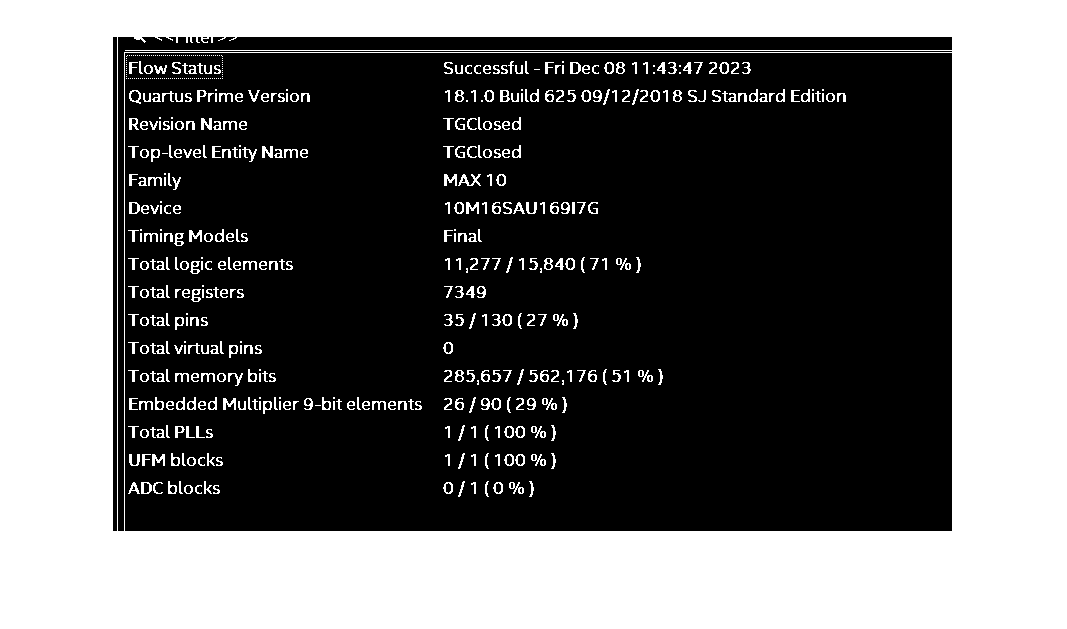

[FileName,PathName] = uigetfile({'*.png';'*.jpg';'*.bmp';'*.*'},'please choose the picture file');

FileName = [PathName,FileName];
OrgPic   = imread(FileName);
%转成灰度图或二值图，这里转成二值图
PicBin  = im2bw(OrgPic,0.8);
PicBin  = imcomplement(PicBin);%对二值图取反，保证背景为黑色
GrayPicSize = size(PicBin);
figure('Name','Original Picture');
title('原图');
imshow(PicBin);

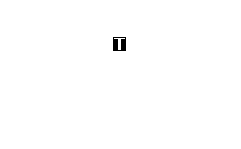

%从图像中提取需要的特征，这里提取字母T
ExtrFtu = PicBin(81:94,330:342);
figure("Name",'Feature Info.');
title('待提取特征');
imshow(ExtrFtu);

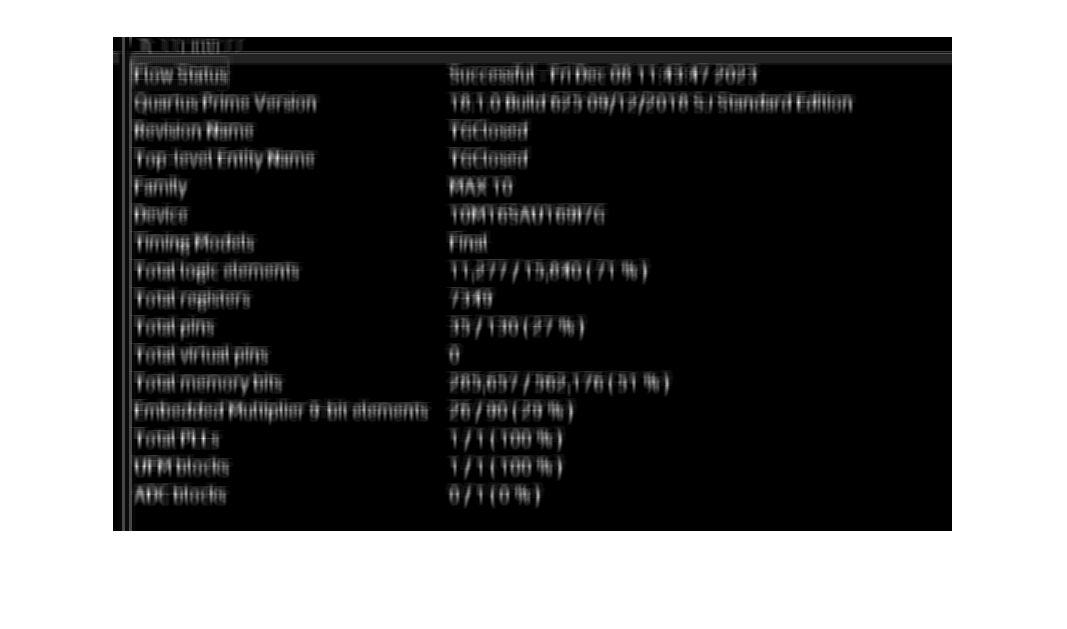

%对原图和待提取特征图做FFT
PicBinFurier = fft2(PicBin);
ExtrFtuFurier= fft2(ExtrFtu,GrayPicSize(1),GrayPicSize(2));
%将原图和特征图的FFT结果做乘积
FFTMuti = PicBinFurier.*ExtrFtuFurier;
%将原图和特征图的FFT乘积结果做FFT逆变换(频域的乘积等于时域的卷积)
InvertFFT = real(ifft2(FFTMuti));
figure("Name",'卷积结果');
imshow(InvertFFT,[]);

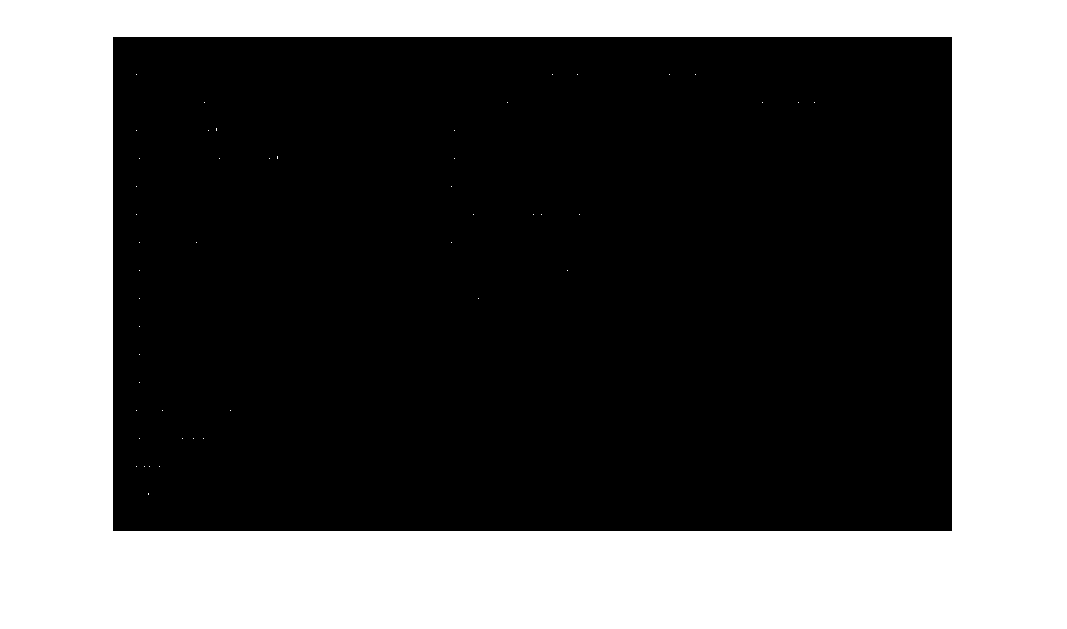

%计算InvertFFT的最大值,选择一个略小于最大值的值作为阈值
maxInv = max(InvertFFT(:));
thresh = maxInv * 0.8;
figure("Name",'特征字符位置');
imshow(InvertFFT > thresh);